DetectCommon

第一步：计算图像的自相似描述子

每一个像素都对应一个描述子，合起来是一个描述子矩阵

一张图计算描述子差不多要跑八分钟。。。。。。

所以我把它们都resize成[100,150]这样算的快些，差不多1分钟吧

patchsize=5;regionsize=61;alpha=-0.5;orientations=10;radialDirections=3;

for m=1:5
   i=1
   src_img = (imread([num2str(m),'.jpg']));
   src_img = imresize(src_img,[100 150],"bicubic");
   src_img = im2double(im2gray(src_img))
   ssdescriptor = getSSdescriptor(src_img,patchsize,regionsize,alpha,orientations,radialDirections);
   savePath = sprintf('ssdescriptor%d.mat', m);
   save(savePath,'ssdescriptor');  % 保存每副图像的自相似性描述子mat
end

设置矩形框大小：w=40，h=60

计算显著性得分

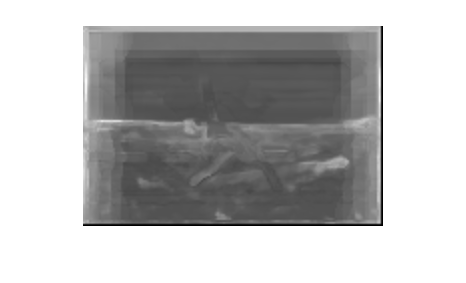

位置 1 处的索引无效。数组索引必须为正整数或逻辑值。

出错 draw_result (第 15 行)
rect_img(x-floor(region_size(1)/2):x+floor(region_size(1)/2),y-floor(region_size(2)/2):y+floor(region_size(2)/2))=128;

width = 100;height = 100;%设置子图像大小为100*100
center_sub = [floor(width/2), floor(height/2)];
p = 1;

n_img=5;
ssdescriptor=cell(1,n_img);
for m = 1:n_img
    Path = sprintf('ssdescriptor%d.mat', m);
    temp = load(Path);%载入图像的自相似性描述子
    ssdescriptor = temp.ssdescriptor;
    img_size1 = size(ssdescriptor);
    src_img = (imread([num2str(m),'.jpg']));
    imgRgb = imresize(src_img,1/2);
    sig_score_img = zeros(img_size1(1),img_size1(2));
    for row1 = center_sub(1)+1:img_size1(1)-center_sub(1)-1
        for col1 = center_sub(2)+1:img_size1(2)-center_sub(2)-1                 
            sub1 = ssdescriptor(row1-center_sub(1):row1+center_sub(1),col1-center_sub(2):col1+center_sub(2),:);%第一幅图像的子图像
            max_match = zeros(1, n_img-1);%记录与其他各个图像的块的最大匹配得分
            num_img=1;
            match_score = cell(n_img);%记录与其他各个图像的块的匹配得分
            %计算与其他图像的相似性
            for n = 1:n_img               
                if n~=m
                    Path = sprintf('ssdescriptor%d.mat', n);
                    temp = load(Path);
                    ssdescriptor2 = temp.ssdescriptor;                   
                    %temp1 = repmat(sub1,[size(ssdescriptor2,1),size(ssdescriptor2,2)]);
                    temp1 = repmat(sub1,[size(ssdescriptor2,1),size(ssdescriptor2,2)]);
                    temp2 =-1.*(sum((ssdescriptor2 - temp1).^2,3));
                    max_match(1,num_img) = max(max(temp2));%记录与每副图像的最大匹配得分
                    match_score{num_img} = reshape(temp2,[],1);           
                    num_img=num_img+1;
                end
            end
            %计算显著性得分
            temp3 = [match_score{1};match_score{2}];%;match_score{3};match_score{4};match_score{5}
            avgMatch = mean(temp3);%该像素点处的矩形框在其它所有图像中的平均匹配得分
            stdMatch = std(temp3);%匹配得分标准差
            sig_score_img(row1,col1) = sum((max_match(:)-avgMatch(:))./stdMatch(:));
        end
     end

    savePath = sprintf('sig_img11%d.mat', m);
	save(savePath,'sig_score_img');  % 保存每副图像显著性得分mat
	
	Path = sprintf('sig_img11%d.mat', m);
    temp = load(Path);
    sig_score_img = temp.sig_score_img;
    src_img = (imread([num2str(m),'.jpg']));
    draw_result(src_img, sig_score_img./4, [61, 61],2);%框出每幅图片检测到的共同目标
     
end